# Nastavenie parametrov robotickeho manipulátora

clc;clear;

l1 = 203;
l2 = 178;
l3 = 178;

phi1_min = -90;
phi1_max = 90;
phi2_min = -55;
phi2_max = 125;
phi3_min = 0;
phi3_max = 150;

phi1 =0;
phi2 =45;
phi3 =45;

% cs for CoordinateSystem
cs.i(:,1) = [50; 0; 0; 1];
cs.j(:,1) = [0; 50; 0; 1];
cs.k(:,1) = [0; 0; 50; 1];
bod(:,1) = [0; 0; 0; 1];

krokXY = 5;
krokXZ = 5;

# Výpočet robotického manipulátora

#### Rotácia R1z

cs.i(:,2) = (rob_rotate('z','deg',90-phi1)*cs.i(:,1));
cs.j(:,2) = (rob_rotate('z','deg',90-phi1)*cs.j(:,1));
cs.k(:,2) = (rob_rotate('z','deg',90-phi1)*cs.k(:,1));

#### Translácia T2z

bod(:,2) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*bod(:,1));
cs.i(:,3) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*cs.i(:,1));
cs.j(:,3) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*cs.j(:,1));
cs.k(:,3) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*cs.k(:,1));

#### Rotácia R3y

cs.i(:,4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*cs.i(:,1));
cs.j(:,4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*cs.j(:,1));
cs.k(:,4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*cs.k(:,1));

#### Translácia T4z

bod(:,3) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*bod(:,1));
cs.i(:,5) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*cs.i(:,1));
cs.j(:,5) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*cs.j(:,1));
cs.k(:,5) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*cs.k(:,1));

#### Rotácia R5y

cs.i(:,6) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*cs.i(:,1));
cs.j(:,6) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*cs.j(:,1));
cs.k(:,6) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*cs.k(:,1));

#### Translácia T6z

bod(:,4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
cs.i(:,7) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*cs.i(:,1));
cs.j(:,7) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*cs.j(:,1));
cs.k(:,7) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*cs.k(:,1));

# Výpočet pracovného priestoru XY

xy_iter = 1;

% Algoritmus pre výpočet XY pracovného priestoru, prepočítaním 
% vzdialenosti vektoru XY od počiatku [0,0,l1] so zaznamenávaním si 
% len významných bodov, ktorých vzdialenosť od počiatku je väčšia ako v 
% danom uhle zaznamenaná.
for(phi1 = phi1_min:krokXY:phi1_max)
    xy(1:4,xy_iter) = 0;
    for(phi2 = phi2_min:krokXY:0)
        for(phi3 = phi3_min:krokXY:phi3_max)
            Ct(1:4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
            Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
            if(xy(4,xy_iter) < Ct(5))
                xy(:,xy_iter) = [Ct(1);Ct(2);l1;Ct(5)];
            end
        end
    end
    xy_iter = xy_iter + 1;
end

for(phi1 = phi1_min:krokXY:phi1_max)
    xy(1:4,xy_iter) = 0;
    for(phi2 = 0:krokXY:phi2_max)
        for(phi3 = phi3_min:krokXY:phi3_max)
            Ct(1:4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
            Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
            if(xy(4,xy_iter) < Ct(5))
                xy(:,xy_iter) = [Ct(1);Ct(2);l1;Ct(5)];
            end
        end
    end
    xy_iter = xy_iter + 1;
end
xy(1:4,xy_iter)=xy(1:4,1);

# Výpočet pracovného priestoru ABC - XZ

xz_iter = 1;

phi1 = 0;
phi2 = phi2_min;
for(phi3 = phi3_min:krokXZ:phi3_max)
    Ct(1:4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
    xz(:,xz_iter) = [Ct(1),Ct(2),Ct(3),Ct(5)];
    xz_iter = xz_iter + 1;
end

phi3 = phi3_max;
for(phi2 = phi2_min:krokXZ:phi2_max)
    Ct(1:4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
    xz(:,xz_iter) = [Ct(1),Ct(2),Ct(3),Ct(5)];
    xz_iter = xz_iter + 1;
end

phi2 = phi2_max;
for(phi3 = phi3_max:-krokXZ:phi3_min)
    Ct(1:4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
    xz(:,xz_iter) = [Ct(1),Ct(2),Ct(3),Ct(5)];
    xz_iter = xz_iter + 1;
end

phi3 = phi3_min;
for(phi2 = phi2_max:-krokXZ:phi2_min)
    Ct(1:4) = (rob_rotate('z','deg',90-phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
    xz(:,xz_iter) = [Ct(1),Ct(2),Ct(3),Ct(5)];
    xz_iter = xz_iter + 1;
end

# Vykreslenie údajov

#### Nastavenie grafických prvkov pre jednotné zobrazenie

figure; 
hold on; 
grid on;
axis equal;
xlim([-400 400]);
ylim([-400 400]);
zlim([-100 600]);
view([130 30]);
xlabel("'x' axis [mm]");
ylabel("'y' axis [mm]");
zlabel("'z' axis [mm]");

#### Vykreslenie ramien 0-A, A-B, B-C

for (iterator = 2:1:length(bod))
    rob_plot3(bod(:,iterator-1),bod(:,iterator))
    rob_sphere(7,bod(:,iterator))
end

#### Vykreslenie súradnicových systémov v bodoch 0,A,B a v koncovom bode manipulátora C

% Kvôli indexovaniu v matlabe sú dané indexy mätúce
rob_plotCS(bod, cs, 1, 2); % Vykresľujeme súradnice z bodu 0 (1) do Rz1*cs (2)
rob_plotCS(bod, cs, 2, 3); % Vykresľujeme súradnice z bodu A (2) do Rz1*Tz1*cs (3)
rob_plotCS(bod, cs, 3, 5); % Vykresľujeme súradnice z bodu B (3) do Rz1*Tz1*Ry2*Ty2*cs (5)
rob_plotCS(bod, cs, 4, 7); % Vykresľujeme súradnice z bodu C (4) do Rz1*Tz1*Ry2*Ty2*Ry3*Ty3*cs (3)

#### Vykreslenie pracovného priestoru XY

fill3(xy(1,:),xy(2,:),xy(3,:),'r','EdgeColor','none','FaceColor','red','FaceAlpha','0.2');
plot3(xy(1,:),xy(2,:),xy(3,:),'Color','red','LineWidth',2);

#### Vykreslenie pracovného priestoru ABC - XZ

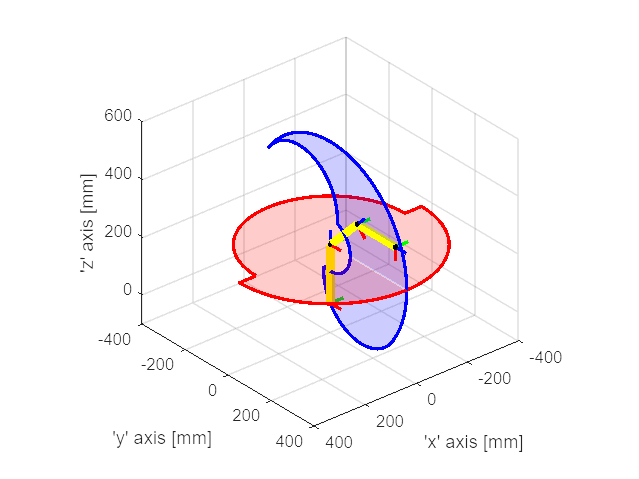

fill3(xz(1,:),xz(2,:),xz(3,:),'b','EdgeColor','none','FaceColor','blue','FaceAlpha','0.2');
plot3(xz(1,:),xz(2,:),xz(3,:),'Color','blue','LineWidth',2);